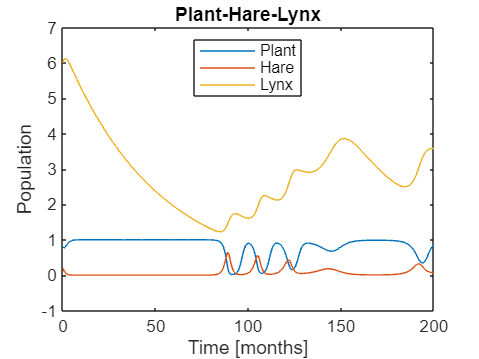

t0 = 0;                 	% start time of simulation [in months]
tfinal = 200;                % end time of simulation [in months]
y0= [0.8 0.2 6];               % initial state i.e. number of plants, hares and lynxs at t=0
tspan = [t0 tfinal];        % time span defined by the start and end times of the simulation [in months]
m1 = 2;
m2 = 0.2;
h1 = 0.4;
h2 = 0.6;
d1= 0.4;
d2=0.02;

[t,y] = ode23(@(t,y) phl_tom(t,y,m1,m2,h1,h2,d1,d2), tspan, y0);

% plotting the population over time
figure("Name",'hare-lynx');
plot(t,y)
title('Plant-Hare-Lynx');
xlabel('Time [months]');
ylabel('Population');
legend('Plant','Hare','Lynx','Location','north');

figure("Name",'State space')
plot3(y(:,1),y(:,2),y(:,3))
title('State space')
xlabel('Plant Population')
ylabel('Hare Population')
zlabel('Lynx Population')